# **Ubicación de polos por respuesta en el tiempo**

Se propone el control por ubicación de polos de un sistema de velocidad constante o velocidad crucero. El objetivo del control es seguir la velocidad de referencia proporcionada. La perturbación del sistema está dada por un cambio en el ángulo del terrero (α).

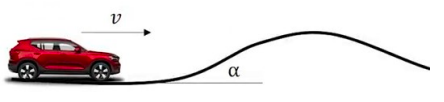

El modelo matemático de la planta está dado por:

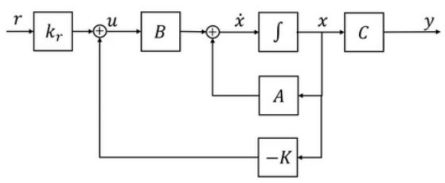

El modelo del sistema dinámico linealizado cuando el vehículo se desplaza a 20 m/s en una carretera plana, viene dado por:

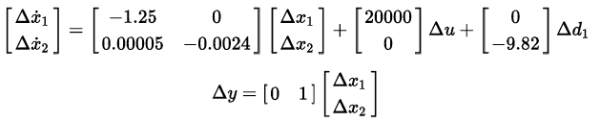

donde Δx1 es la fuerza en las ruedas, Δx2 es la velocidad en las ruedas, Δu es la señal de entrada y Δd1 es la perturbación.

En el siguiente modelo de control de velocidad crucero, 

**1)** Verifique si el sistema es controlable.

Dada la matriz de controlabilidad:


$$C=\left\lbrack B\;\mathrm{AB}\right\rbrack$$


Sabemos que el sistema es controlable si el rango de la matriz anterior es 'n', siendo n el orden del sistema.

close all; clear all; clc;
A = [-1.25    0;
     0.00005 -0.0024];
Bu = [20000;0];
Bp = [0;-9.82];
B = Bu;
C = [0 1];
D = [0];
I = eye(2);
Controlabilidad = [Bu A*Bu];
r = rank(Controlabilidad);
disp('El rango de la matriz de controlabilidad es:')

El rango de la matriz de controlabilidad es:


disp(r)

     2



**2)** Determine el polinomio deseado con ωn=0.6 y ζ= 1/√2 . Encuentre el valor de la matriz K. 

% Coeficientes polinomio característico.
syms s; % Variable compleja.
disp('Polinomio característico del sistema:')

Polinomio característico del sistema:


p_caracteristico = det(s*I-A);
expand(p_caracteristico)

$$ans = s^{2}+\frac{3131\,s}{2500}+\frac{3}{1000}$$

C1_syms = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
C1_double = double(C1_syms); % Coeficientes formato double.
a2 = C1_double(1,1);
a1 = C1_double(1,2);

% Coeficientes polinomio deseado.
wn = 0.6; % Frecuencia natural.
zeta = 1/sqrt(2); % Amortiguamiento relativo.
disp('Polinomio deseado:')

Polinomio deseado:


p_deseado = (s^2 + 2*zeta*wn*s + wn^2) % Polinomio deseado.

$$p\_deseado = s^{2}+\frac{3\,\sqrt{2}\,s}{5}+\frac{9}{25}$$

C2_syms = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
C2_double = double(C2_syms); % Coeficientes en formato double.
p2 = C2_double(1,1);
p1 = C2_double(1,2);

% Diseño del controlador.
Wr = [B A*B]; % Matriz de alcanzabilidad.
Wr_tilde = inv([1 a1;
                0 1]);
disp('Matriz de ganancias del controlador:')

Matriz de ganancias del controlador:


K = [p1-a1 p2-a2]*Wr_tilde*inv(Wr)

K =    -0.0000    0.3580


% Corroboración.
Kprima = acker(A,B,roots([1 2*zeta*wn wn^2]))

Kprima =    -0.0000    0.3580


**3)** Determine el valor de kr. El vehículo está viajando a 20 m/s sobre una ruta plana. La perturbación se considera nula.

disp('Valor de kr:')

Valor de kr:


kr = -1/(C*inv(A-B*K)*B)

kr = 0.3600

**4)** Utilice los archivos CruiseCtrl_StateFeedback.slx y CruiseCtrl_StateFeedback_design.m para graficar.

Se observa como para el caso en el que no hay perturbación la referencia de velocidad se sigue correctamente.

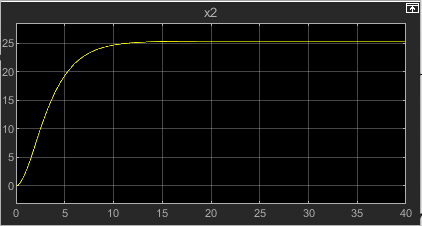

En este caso se toma una referencia de 20 m/s donde a los 1s se produce un cambio de referencia a 25 m/s para la velocidad del auto.

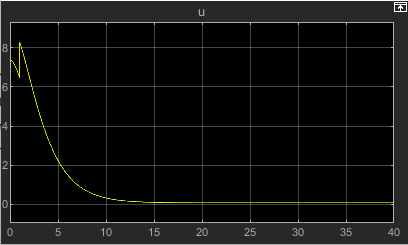

El gráfico anterior se corresponde con la acción de control.

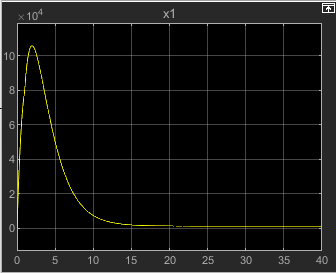

Este gráfico se corresponde con la fuerza del motor.